x

x =     0.0872
    0.0872
    0.0872
    0.0872
    0.0872
    0.0874
    0.0914
    0.0983
    0.1038
    0.1040


y

y =     2.0962
    2.0962
    2.0962
    2.0962
    2.0961
    2.0937
    2.0480
    1.9703
    1.9078
    1.8985


theta

theta =     3.0543
    3.0543
    3.0543
    3.0543
    3.0543
    3.0541
    3.0501
    3.0431
    3.0376
    3.0374


dtheta

dtheta =          0
   -0.0002
   -0.0012
   -0.0062
   -0.0313
   -0.1557
   -0.6130
   -0.7050
   -0.3286
    0.3074


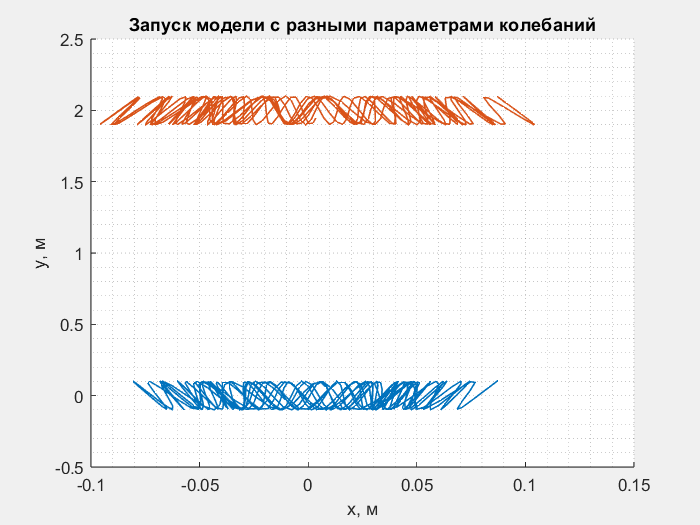

%Для нижнего положения равновесия
startDegree = 5;
sim('kapitsa_pendulum.slx',5); 
x_low = x;
y_low = y;
theta_low = theta;
dtheta_low = dtheta;

%Для верхнего положения равновесия
startDegree = 175;
sim('kapitsa_pendulum.slx',5); 
x_up = x;
y_up = y;
theta_up = theta;
dtheta_up = dtheta;


fig1 = figure();
set(fig1,'Visible','on');
hold all;
grid('minor');
xlabel('x, м') 
ylabel('y, м') 
title('Запуск модели c разными параметрами колебаний');
plot(x_low, y_low,'DisplayName','Нижнее положение','LineWidth',1)
plot(x_up, y_up,'DisplayName','Верхнее положение','LineWidth',1)

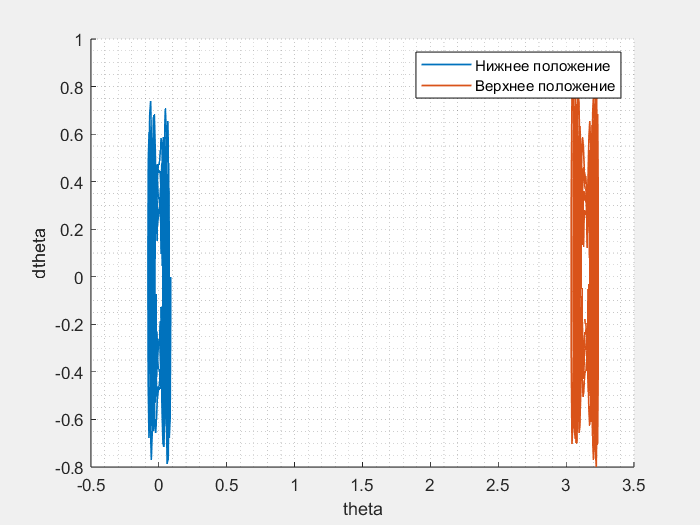



fig2 = figure();
set(fig2,'Visible','on');
hold all;
grid('minor');
xlabel('theta') 
ylabel('dtheta') 
plot(theta_low, dtheta_low,'DisplayName','Нижнее положение','LineWidth',1)
plot(theta_up, dtheta_up,'DisplayName','Верхнее положение','LineWidth',1)

legend();

%Задание 3
startDegree = 120;

%Случай один: Частота подвеса < частоты маятника
Freq = 1\2\pi

Freq = 1.5708

sim('kapitsa_pendulum.slx',10); 
x_1 = x;
y_1 = y;
theta_1 = theta;
dtheta_1 = dtheta;

%Случай два: Частота подвеса = частоты маятника
Freq = pi\2\pi

Freq = 4.9348

sim('kapitsa_pendulum.slx',10); 
x_2 = x;
y_2 = y;
theta_2 = theta;
dtheta_2 = dtheta;
%Случай три: Частота подвеса > частоты маятника
Freq = 10\2\pi

Freq = 15.7080

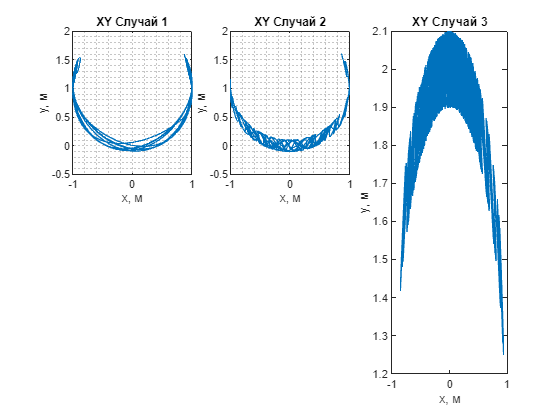

sim('kapitsa_pendulum.slx',10); 
x_3 = x;
y_3 = y;
theta_3 = theta;
dtheta_3 = dtheta;


grid('minor');
xlabel('x, м') 
ylabel('y, м') 
subplot(2,3,1);
plot(x_1, y_1)
title('XY Случай 1')


grid('minor');
xlabel('x, м') 
ylabel('y, м') 
subplot(2,3,2);
plot(x_2, y_2)
title('XY Случай 2')

grid('minor');
xlabel('x, м') 
ylabel('y, м') 

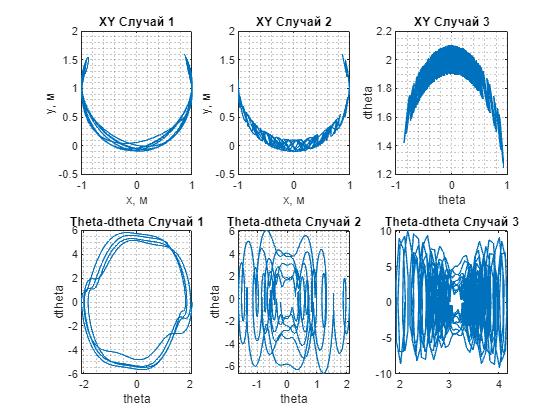

subplot(2,3,3);
plot(x_3, y_3)
title('XY Случай 3')

grid('minor');
xlabel('theta') 
ylabel('dtheta') 
subplot(2,3,4);
plot(theta_1, dtheta_1)
title('Theta-dtheta Случай 1')

grid('minor');
xlabel('theta') 
ylabel('dtheta')
subplot(2,3,5);
plot(theta_2, dtheta_2)
title('Theta-dtheta Случай 2')

grid('minor');
xlabel('theta') 
ylabel('dtheta')
subplot(2,3,6);
plot(theta_3, dtheta_3)
title('Theta-dtheta Случай 3')